# Summary Excercise of Chapter 4

% import the content of hhps://www.riani.it/Start.xlsx into a variable X
XX = webread('http://www.riani.it/start.xlsx');

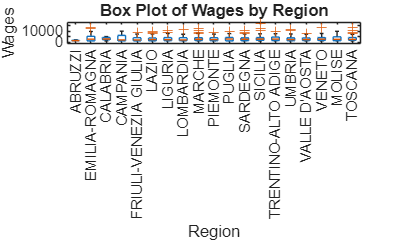

% PLOT  abox plot of wages by region
boxplot(XX.Retribuzione, XX.Regione);
xlabel('Region');
ylabel('Wages');
title('Box Plot of Wages by Region');

% using box chart
boxchart(categorical( XX.Regione),XX.Retribuzione)
xlabel('Region');
ylabel('Wages');
title('Box Chart of Wages by Region');

% using table X and Xt , extract the indicators "ANZIANI" ("elderly
% People") and BAMBINI for ("Children") for the province of genova, Retrive
% from both x and Xt
!git clone https://github.com/IlSole24ORE/QDV2022.git

fatal: destination path 'QDV2022' already exists and is not an empty directory.



x=('D:\2018\Github_Push\Data_Science\Data_Science_With_matlab\QDV2022\20221213_QDV2022_001.csv')

x = 'D:\2018\Github_Push\Data_Science\Data_Science_With_matlab\QDV2022\20221213_QDV2022_001.csv'


x=readtable(x);

today=datetime("today");

datetime(today:10:today+60)

ans = 1×8 datetime array
   29-Nov-2025   09-Dec-2025   19-Dec-2025   29-Dec-2025   08-Jan-2026   18-Jan-2026   28-Jan-2026   07-Feb-2026


Y=sesame(fil1,:)

Y = 15×2 timetable
      time          yQIN          yQPK   
    _________    __________    __________

    01-Jan-21    1.9981e+05    5.9837e+05
    01-Feb-21    1.3175e+05    8.8254e+05
    01-Mar-21    1.2016e+06    1.0402e+06
    01-Apr-21    1.9594e+06    1.4639e+06
    01-May-21    2.5824e+06    8.8886e+05
    01-Jun-21    1.5504e+06    7.3338e+05
    01-Jul-21    2.0808e+06    6.0163e+05
    01-Aug-21    1.6606e+06    6.8835e+05
    01-Sep-21     2.058e+06    1.0618e+06
    01-Oct-21    2.1042e+06    6.5234e+05
    01-Nov-21    1.3498e+06    9.7787e+05
    01-Dec-21    1.2624e+06    1.0162e+06
    01-Jan-22    1.3683e+06    7.5525e+05
    01-Feb-22

% compute the mean and median of both series in the interval, of time table
% Y
meanYQin =mean(Y.yQIN);
medianYQin = median(Y.yQIN);
meanYQpk = mean(Y.yQPK);
medianYQpk = median(Y.yQPK);
disp(['Mean of yQIN: ', num2str(meanYQin)]);

Mean of yQIN: 1480622.4475


disp(['Median of yQIN: ', num2str(medianYQin)]);

Median of yQIN: 1550422.09


disp(['Mean of yQPK: ', num2str(meanYQpk)]);

Mean of yQPK: 867564.9326


disp(['Median of yQPK: ', num2str(medianYQpk)]);

Median of yQPK: 871822.4


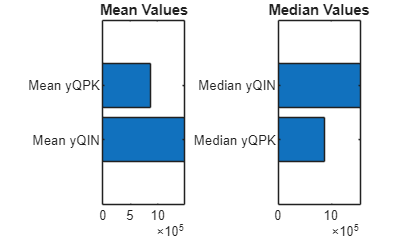

%plot them in horizontal panal
% Create a horizontal panel for the mean and median values
figure;
subplot(1, 2, 1);
barh([meanYQin, meanYQpk]);
set(gca, 'yticklabel', {'Mean yQIN', 'Mean yQPK'});
title('Mean Values');
subplot(1,2,2)
barh([medianYQpk medianYQin])
set(gca, 'yticklabel', {'Median yQPK', 'Median yQIN'});
title('Median Values');

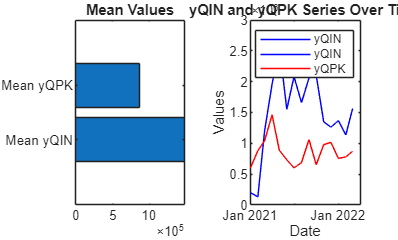

% plot the two yQIN and yQPK series over time 
plot(Y.time, Y.yQIN, 'b-', 'DisplayName', 'yQIN');
hold on;
plot(Y.time, Y.yQPK, 'r-', 'DisplayName', 'yQPK');
xlabel('Date');
ylabel('Values');
title('yQIN and yQPK Series Over Time');
legend show;
hold off;

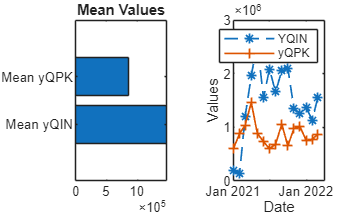

plot(Y.time, Y.yQIN,LineStyle="--",LineWidth=1,Marker="*",DisplayName='YQIN');
hold on
plot(Y.time,Y.yQPK,LineStyle="-",LineWidth=1,Marker="+",DisplayName='yQPK')
xlabel('Date');
ylabel('Values');
legend("show")
hold off